Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), 1000000, Timeout=2);
configureTerminator(STM32_ser,"CR");

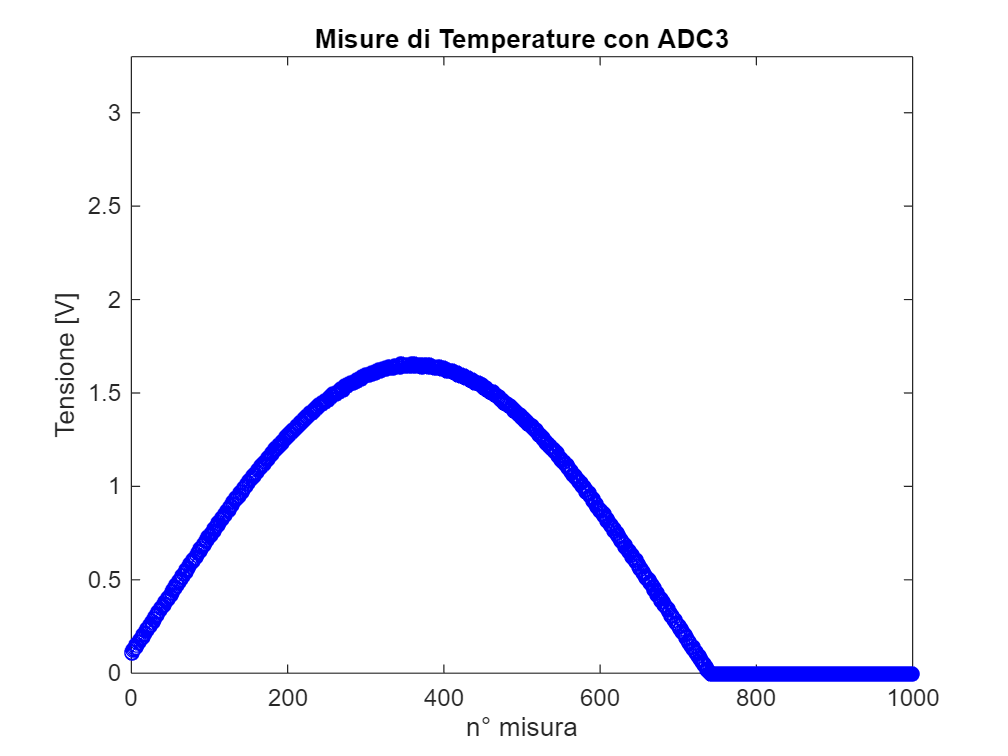

buff_size = 1000;
f = figure;

while 1
    STM32_ser.flush;
    STM32_ser.write('e','char');
    buff_data = STM32_ser.read(buff_size,'uint16');
    
    buff_data = buff_data ./ 2^16 * 3.3;

    plot(1:buff_size, buff_data, 'b-o');
    
    title("Misure di Temperature con ADC3");
    xlabel("n° misura");
    ylabel("Tensione [V]");
    ylim([0,3.3]);
    
end